clc; clear; close all;

load("data3.mat")
data

data = Simulink.SimulationData.Dataset 'data' with 3 elements

                         Name     BlockPath        
                         _______  ________________ 
    1  [1x1 Signal]      TCP_ang  robot/Integrator
    2  [1x1 Signal]      TCP      robot/Mux       
    3  [1x1 Signal]      HOG      robot/Mux1      

  - Use braces { } to access, modify, or add elements using index.


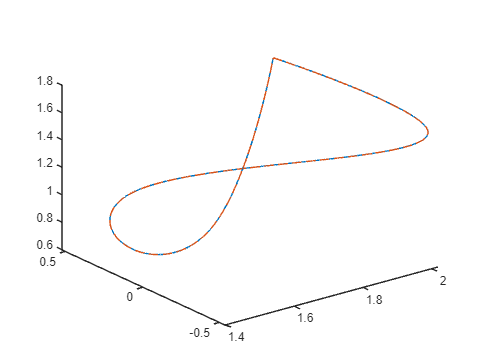


ang = data{1}.extractTimetable;
tcp = data{2}.extractTimetable;
hog = data{3}.extractTimetable;
tcp.TCP(:, 1);

% plot(tcp.Time, -tcp.TCP(:, 1), LineWidth=2)
% grid on;
% hold on;
% plot(hog.Time, -hog.HOG(:, 1), '--', LineWidth=2)
% plot(tcp.Time, -tcp.TCP(:, 2), LineWidth=2)
% plot(hog.Time, -hog.HOG(:, 2), '--', LineWidth=2)
% plot(tcp.Time, -tcp.TCP(:, 3), LineWidth=2)
% plot(hog.Time, -hog.HOG(:, 3), '--', LineWidth=2)



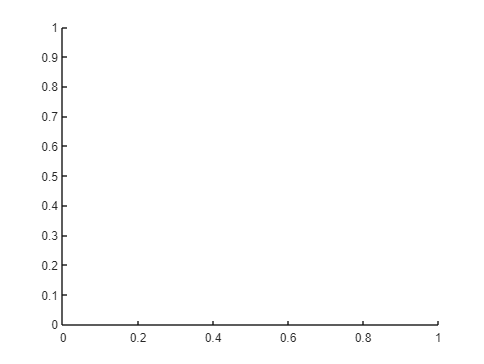

% legStr = {'$x(t)$, measured', '$x(t)$, setpoint', '$y(t)$, measured',...
%     '$y(t)$, setpoint', '$z(t)$, measured', '$z(t)$, setpoint'};
% legend(legStr, NumColumns=3, Interpreter="latex")
% hold off

% Plotting for the repport
W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot
fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

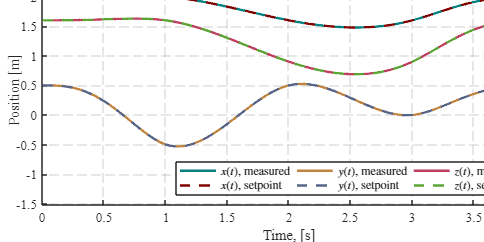


% Figure 1
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];

hold on
plt1 = plot(tcp.Time, -tcp.TCP(:, 1));
plt1.Color = [0 0.502 0.502];%'b';    % y, m, c, r, g, b, w, k,
plt1.LineWidth  = LW2;

plt2 = plot(hog.Time, -hog.HOG(:, 1));
plt2.Color = [0.5 0 0 1];%'r';
plt2.LineStyle = '--';
plt2.LineWidth = LW2;

plt3 = plot(tcp.Time, -tcp.TCP(:, 2));
plt3.Color = "#BF8540";%'b';    % y, m, c, r, g, b, w, k,
plt3.LineWidth  = LW2;

plt4 = plot(hog.Time, -hog.HOG(:, 2));
plt4.Color = "#576387";%'r';
plt4.LineStyle = '--';
plt4.LineWidth = LW2;

plt5 = plot(tcp.Time, -tcp.TCP(:, 3));
plt5.Color = "#BF405E";%'b';    % y, m, c, r, g, b, w, k,
plt5.LineWidth  = LW2;

plt6 = plot(hog.Time, -hog.HOG(:, 3));
plt6.Color = "#5AA534";%'r';
plt6.LineStyle = '--';
plt6.LineWidth = LW2;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';             
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
%ax.XTick = 0:0.5:4;  

%ax.XLim = [0:0.5:4]
%ax.YTick = -2:0.5:2;                    % Divisions on axes

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Position [m]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


legStr = {'$x(t)$, measured', '$x(t)$, setpoint', '$y(t)$, measured',...
    '$y(t)$, setpoint', '$z(t)$, measured', '$z(t)$, setpoint'};

leg = legend(legStr, NumColumns=3, Interpreter="latex");
leg.Location = "southeast";

hold off
grid on
box on

xlim([duration(-0,-0,-0) duration(0,0,4)])
ylim([-1.51 2.34])

%filename1 = 'plt_1.eps';
%saveas(fig,filename1, 'epsc');

% Figure 2
clear fig ax
ax = gca;               % Handle for the axis
fig = figure;           % Handle for the figure
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];

hold on
plt1 = plot(tcp.Time, (-tcp.TCP(:, 1) - (-hog.HOG(:, 1)))*1000);
plt1.Color = [0 0.502 0.502];%'b';    % y, m, c, r, g, b, w, k,
plt1.LineWidth  = LW2;

plt2 = plot(tcp.Time, (-tcp.TCP(:, 2) - (-hog.HOG(:, 2)))*1000);
plt2.Color = [0.5 0 0 1];%'r';
%plt2.LineStyle = '--';
plt2.LineWidth = LW2;

plt3 = plot(tcp.Time, (-tcp.TCP(:, 3) - (-hog.HOG(:, 3)))*1000);
plt3.Color = "#BF8540";%'b';    % y, m, c, r, g, b, w, k,
plt3.LineWidth  = LW2;


ax.Units = 'centimeters';
ax.GridLineStyle = '--';             
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above

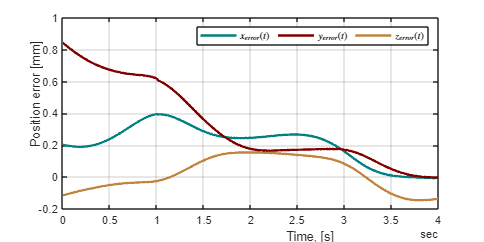

            

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Position error [mm]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];


legStr = {'$x_{error}(t)$', '$y_{error}(t)$', '$z_{error}(t)$'};

leg = legend(legStr, NumColumns=3, Interpreter="latex");
leg.Location = "northeast";
xlim([duration(-0,-0,-0) duration(0,0,4)])
ylim([-0.2 1])

hold off
grid on
box on



%filename1 = 'plt_2.eps';
%saveas(fig,filename1, 'epsc');

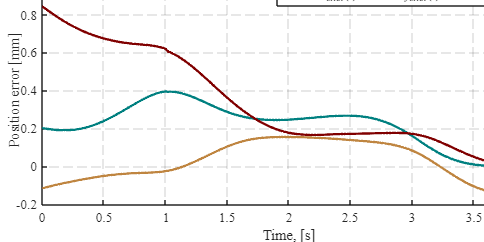

clear fig ax
% Figure 2
ax = gca;               % Handle for the axis
fig = figure;           % Handle for the figure
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];

hold on
plt1 = plot(ang.Time, rad2deg(ang.TCP_ang(:, 1)));
plt1.Color = [0 0.502 0.502];%'b';    % y, m, c, r, g, b, w, k,
plt1.LineWidth  = LW2;

plt2 = plot(ang.Time, rad2deg(ang.TCP_ang(:, 2)));
plt2.Color = [0.5 0 0 1];%'r';
%plt2.LineStyle = '--';
plt2.LineWidth = LW2;

plt3 = plot(ang.Time, rad2deg(ang.TCP_ang(:, 3)));
plt3.Color = "#BF8540";%'b';    % y, m, c, r, g, b, w, k,
plt3.LineWidth  = LW2;


ax.Units = 'centimeters';
ax.GridLineStyle = '--';             
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above

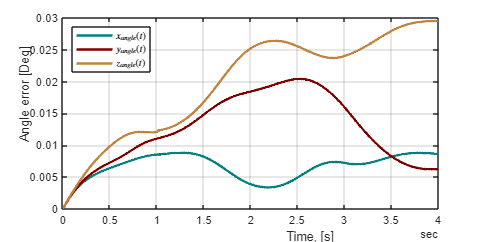

            

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Angle error [Deg]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x-0.3, ylabel_y];


legStr = {'$x_{angle}(t)$', '$y_{angle}(t)$', '$z_{angle}(t)$'};

leg = legend(legStr, Interpreter="latex");
leg.Location = "northwest";
xlim([duration(-0,-0,-0) duration(0,0,4)])
ylim([0 0.03])

hold off
grid on
box on



%filename1 = 'plt_3.eps';
%saveas(fig,filename1, 'epsc');